Inisialisasi Program

%clc;
%clear;
%close all;
global data PL

Inisialisasi DE

CostFunction=@(P) ESinv(P);    % Cost Function

nVar=5;            % Number of Decision Variables

VarSize=[1 nVar];   % Decision Variables Matrix Size

VarMin= 400;          % Lower Bound of Decision Variables
VarMax= 600;          % Upper Bound of Decision Variables

%% DE Parameters

MaxIt=1000;      % Maximum Number of Iterations

nPop=50;        % Population Size

beta_min=0.2;   % Lower Bound of Scaling Factor
beta_max=0.8;   % Upper Bound of Scaling Factor

pCR=0.2;        % Crossover Probability

Inisialisasi Populasi

empty_individual.Position=[];
empty_individual.Cost=[];

BestSol.Cost=inf;

pop=repmat(empty_individual,nPop,1);

for i=1:nPop
   Eg1 = unifrnd(VarMin(1,1),VarMax(1,1));              %Inisialisasi generator
   Eg2 = unifrnd(VarMin(1,1),VarMax(1,1));              
   Eg3 = unifrnd(VarMin(1,1),VarMax(1,1));
   Eg4 = unifrnd(VarMin(1,1),VarMax(1,1));
   Eg5 = unifrnd(VarMin(1,1),VarMax(1,1));
   pop(i).Position = zeros(1,5);                        %Inisialisasi posisi ke matrix populasi
   pop(i).Position= [Eg1 Eg2 Eg3 Eg4 Eg5];             %Input generator ke posisi populasi 
   pop(i).Cost=CostFunction(pop(i).Position); %Mencari obj. function populasi
   
   
   
   if pop(i).Cost<BestSol.Cost
    BestSol=pop(i);
    end 
    
end

BestCost=zeros(MaxIt,1);

Constraint Handling


% 
% for i=1:nPop
%     Gmax = 0
%     feasPop = 0
%     G(pop(i).Position) = max(sum(pop(i).Position)-0.001,0);
%     V(pop(i).Position) = (sum((1/Gmax).*G(pop(i).Position))/(1/Gmax)
%     if sum (pop(i).Position) == PL
%         feasPop = feasPop + 1
%  for i=1:nPop 
%      while sum(pop(i).Position)-PL ~= 0.005
%      if sum(pop(i).Position) < PL
%          pop(i).Position = pop(i).Position + 0.01.*PL
%      elseif sum(pop(i).Position) > PL 
%          pop(i).Position = pop(i).Position - 0.01.*PL
%      end
%      end
%  end
        

## **DE Main Loop**

 for it=1:MaxIt
     
     for i=1:nPop
         
         x=pop(i).Position;
         
         A=randperm(nPop);
         
        A(A==i)=[];
        
        a=A(1);
        b=A(2);
        c=A(3);
         

Mutasi

         beta=unifrnd(beta_min,beta_max);
         beta=unifrnd(beta_min,beta_max,VarSize);
         y=pop(a).Position+beta.*(pop(b).Position-pop(c).Position);

Evaluasi Constraint Mutasi

          y = max(y,VarMin');
          y = min(y,VarMax');

Crossover

        z=zeros(size(x));
        j0=randi([1 numel(x)]);
        for j=1:numel(x)
            if j==j0 || rand<=pCR
                z(j)=y(j);
            else
                z(j)=x(j);
            end
        end
        
        NewSol.Position=z;
        NewSol.Cost=CostFunction(NewSol.Position);
        
        if NewSol.Cost<pop(i).Cost 
            pop(i)=NewSol;
            
            if pop(i).Cost<BestSol.Cost
               BestSol=pop(i);
            end
        end
        
    end
      
    

    Update Best Cost

    BestCost(it)=BestSol.Cost;
    

    Show Iteration Information

%     disp(['Iteration ' num2str(it) ': Best Cost = ' num2str(BestCost(it))]);
%     disp([(pop(1).Position)]);
    
end


 Show Results

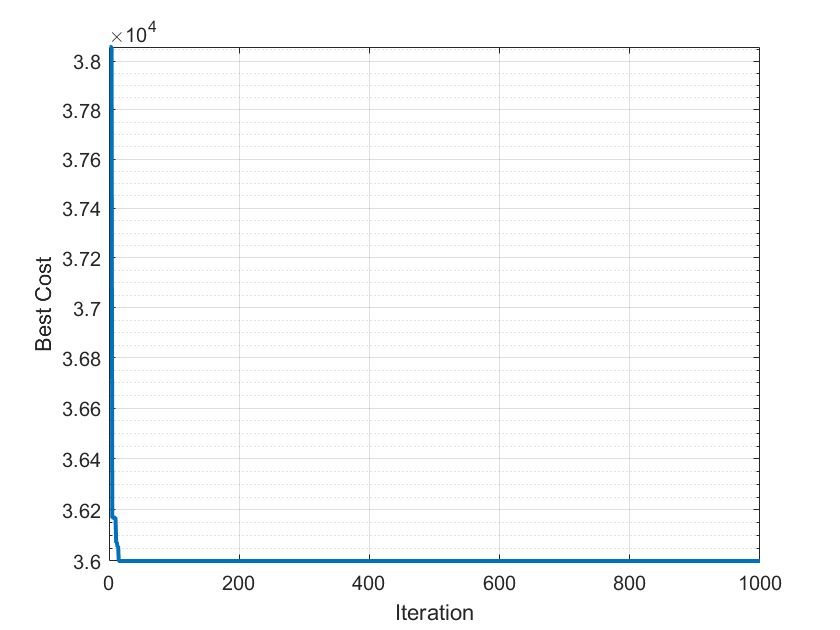

figure;
semilogy(BestCost, 'LineWidth', 2);
xlabel('Iteration');
ylabel('Best Cost');
grid on;


sum(BestSol.Position)

ans = 2000

BestSol

BestSol = struct with fields:
    Position: [400 400 400 400 400]
        Cost: 36000


x = [393.2 334.6 122.2];
ESinv(x);